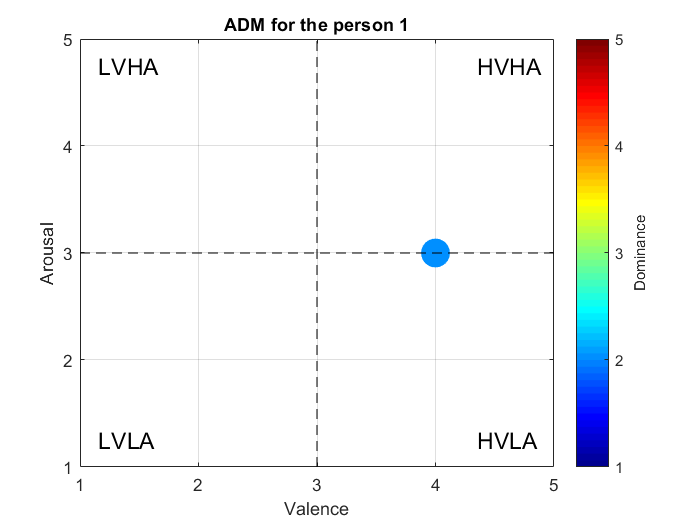

if ~exist('DREAMER','var')
    load("C:\Users\user\Documents\MATLAB\DREAMER.mat");
end

person=1;
x = DREAMER.Data{1,person}.ScoreValence(1,:);
y = DREAMER.Data{1,person}.ScoreArousal(1,:);
c = DREAMER.Data{1,person}.ScoreDominance(1,:);

scatter(x,y,300,c,'filled')
cb=colorbar('XTick',1:5);

xlabel("Valence"),xticks(1:5)
ylabel("Arousal"),yticks(1:5)
cb.Label.String = 'Dominance';
caxis([1 5])
colormap jet

grid on
box on

line([3 3],[1 5],'linestyle','--','color','black')
line([1 5],[3 3],'linestyle','--','color','black')

xt = [1.15 4.35 4.35 1.15];
yt = [4.75 4.75 1.25 1.25];
str = {'LVHA','HVHA','HVLA','LVLA'};
text(xt,yt,str,'FontSize',14)
title("ADM for the person "+num2str(person))
axis([1 5 1 5])

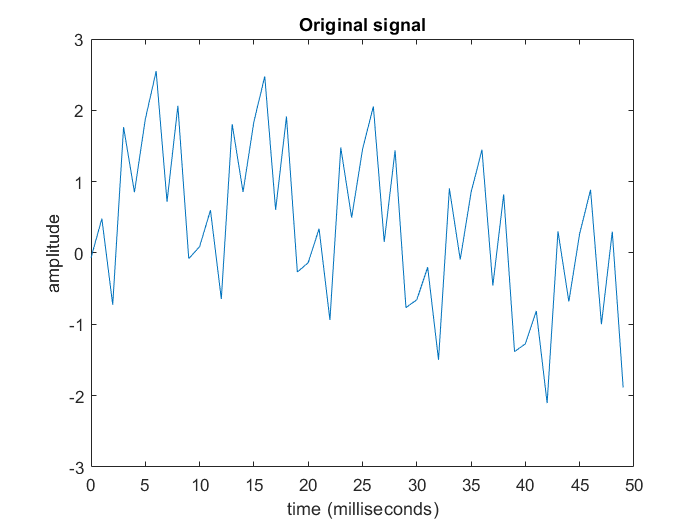

% Basic FFT

Fs=1000; %1kHz
T=1/Fs; %0.001s
L=1500; %1500 samples
t=T*(0:L-1); % 0s to 1.499s

f1=10;f2=100;f3=400;f4=0;
x=sin(2*pi*f1*t+1)+sin(2*pi*f2*t-2)+sin(2*pi*f3*t)+sin(2*pi*f4*t);

plot(1000*t(1:50),x(1:50));title("Original signal");xlabel("time (milliseconds)");ylabel("amplitude");

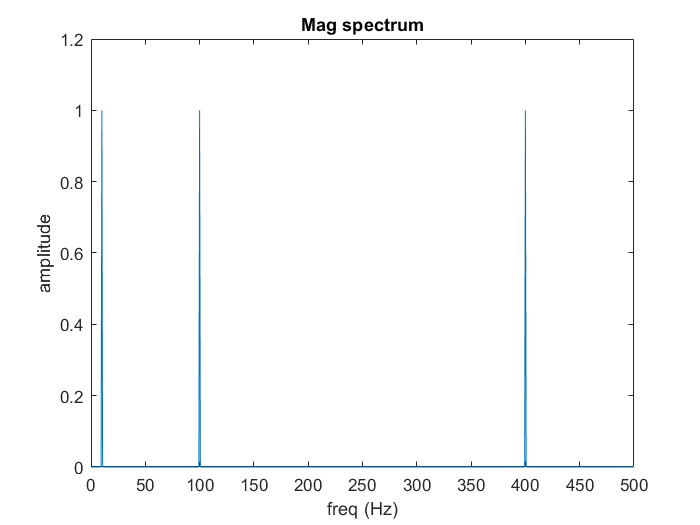


y=fft(x);
f=Fs*(0:(L/2-1))/L;
plot(f,2*abs(y(1:L/2)/L))
title("Mag spectrum");xlabel("freq (Hz)");ylabel("amplitude");

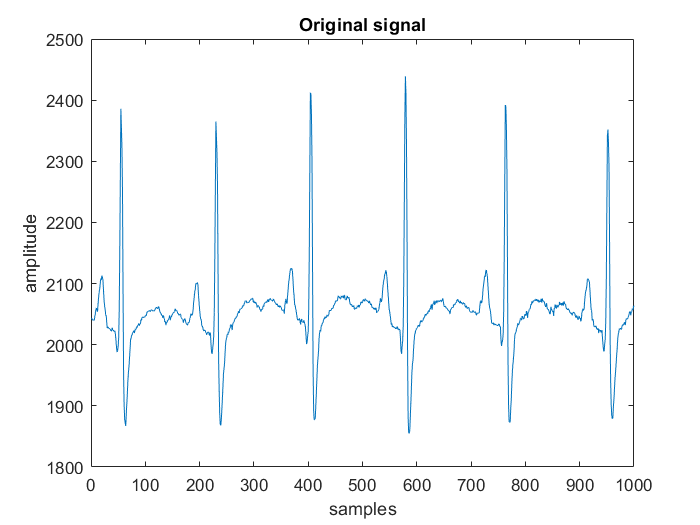

% Stimuli FFT

stimuli=DREAMER.Data{1,1}.ECG.stimuli{1,1}(end-999:end,1);
Fs=DREAMER.ECG_SamplingRate;
L=length(stimuli);
max_amp=max(stimuli);
min_amp=min(stimuli);
normalized_stimuli=(stimuli-min_amp)/(max_amp-min_amp);
plot(stimuli)
title("Original signal");xlabel("samples");ylabel("amplitude");

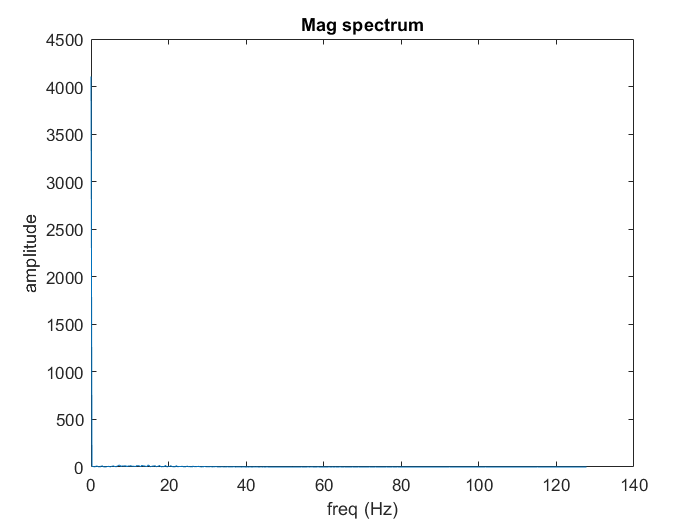

y=fft(stimuli);
f=Fs*(0:L/2-1)/L;
plot(f,2*abs(y(1:L/2)/(L)))
title("Mag spectrum");xlabel("freq (Hz)");ylabel("amplitude");

% Mag spectrum in bin axis
% plot(2*abs(y))
% title("Mag spectrum");xlabel("bins");ylabel("normalized amplitude");

% Heartbeat 
if ~exist('DREAMER','var')
    load("C:\Users\user\Documents\MATLAB\DREAMER.mat");
end
Fs=DREAMER.ECG_SamplingRate;
samples_per_min=Fs*60;
ecgsig=DREAMER.Data{1,1}.ECG.stimuli{1,1}(end-samples_per_min+1:end,1);
t=1:length(ecgsig);
tx=t./Fs;

wt=modwt(ecgsig,4,'sym4');
wtrec=zeros(size(wt));
wtrec(3:4,:)=wt(3:4,:);

y=imodwt(wtrec,'sym4');
y=abs(y).^2;

avg=mean(y);
[Rpeaks,locs]=findpeaks(y,t,'MinPeakHeight',8*avg,'MinPeakDistance',50);

nohb=length(locs);
timelimit=length(ecgsig)/Fs;
hbpermin=(nohb*60)/timelimit;
disp(strcat('Heart Rate= ',num2str(hbpermin)));

Heart Rate=84


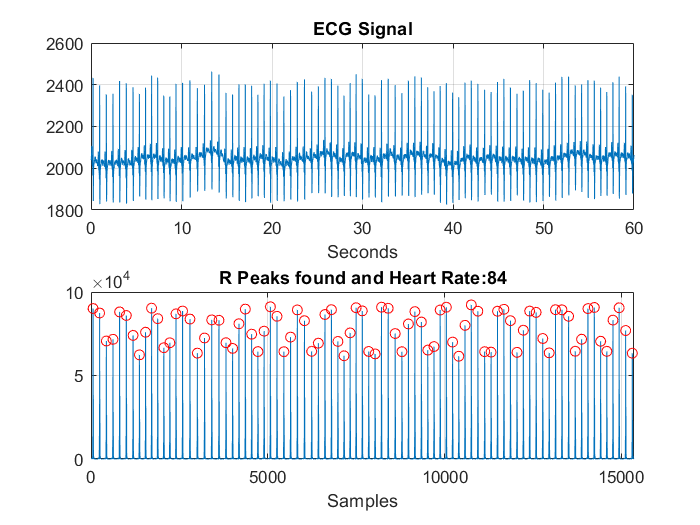


subplot(211);
plot(tx,ecgsig);

xlim([0,timelimit]);
grid on;
xlabel('Seconds');
title('ECG Signal')

subplot(212);
plot(t,y);
grid on;
xlim([0,length(ecgsig)]);
hold on
plot(locs,Rpeaks,'ro');
hold off
xlabel('Samples');
title(strcat('R Peaks found and Heart Rate: ',num2str(hbpermin)));

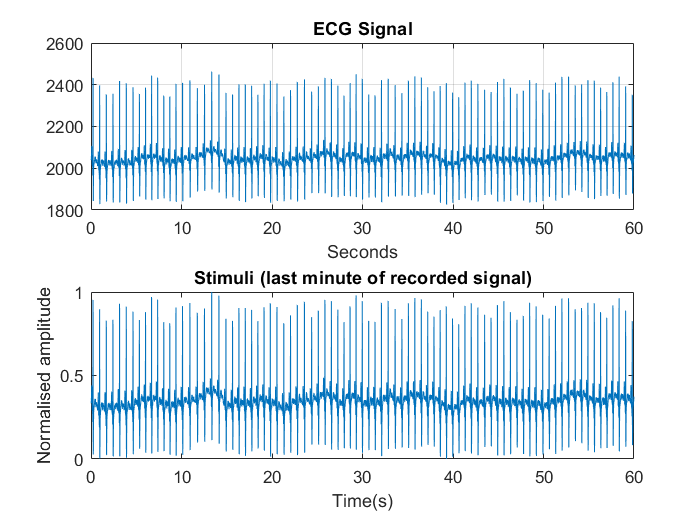

if ~exist('DREAMER','var')
    load("C:\Users\user\Documents\MATLAB\DREAMER.mat");
end

Fs=DREAMER.ECG_SamplingRate;
samples_per_min=Fs*60;

ecg_lastMin=DREAMER.Data{1,1}.ECG.stimuli{1,1}(end-samples_per_min+1:end,1);

ecg_lastMin_normalised=(ecg_lastMin-min(ecg_lastMin))/(max(ecg_lastMin)-min(ecg_lastMin));

plot([0:length(ecg_lastMin_normalised)-1]./Fs,ecg_lastMin_normalised);
xlabel("Time(s)");ylabel("Normalised amplitude");title("Stimuli (last minute of recorded signal)")

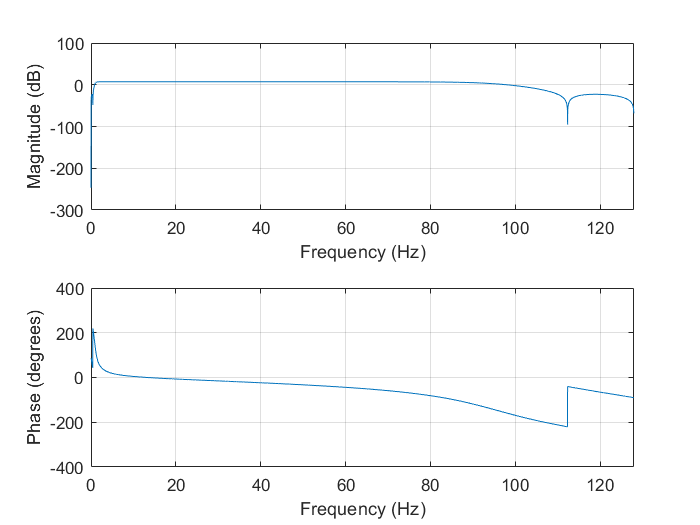

% Remove Baseline wander

Fs = 256;                                               % Sampling Frequency (Hz)
Fn = Fs/2;                                              % Nyquist Frequency
Wp = [1  100]/Fn;                                       % Passband (Normalised)
Ws = [0.5  110]/Fn;                                     % Stopband (Normalised)
Rp = 10;                                                 % Passband Ripple (dB)
Rs = 30;                                                % Stopband Ripple (dB)
[n,Ws] = cheb2ord(Wp, Ws, Rp, Rs);                      % Chebyshev Type II Order
[b,a] = cheby2(n, Rs, Ws);                              % Transfer Function Coefficients
[sos,g] = tf2sos(b,a);                                  % SEcond-Order-Section For STability
figure(1)
freqz(sos, 4096, Fs)  

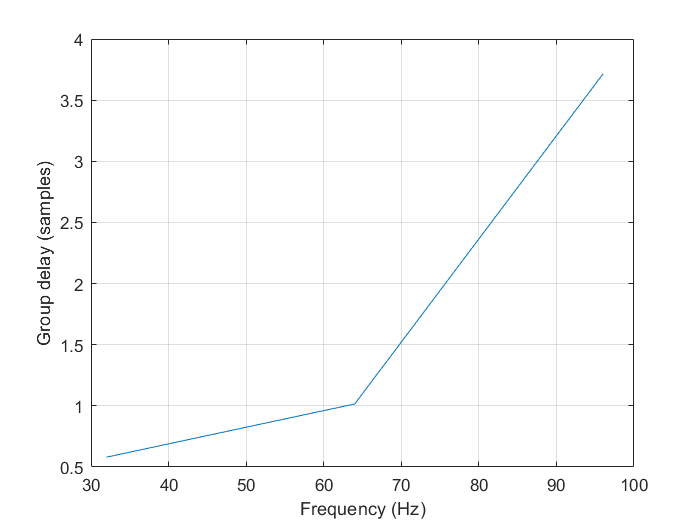

ecg_lastMin_blRemoved=filter(b,a,ecg_lastMin);
grpdelay(b,a,n+1,Fs)

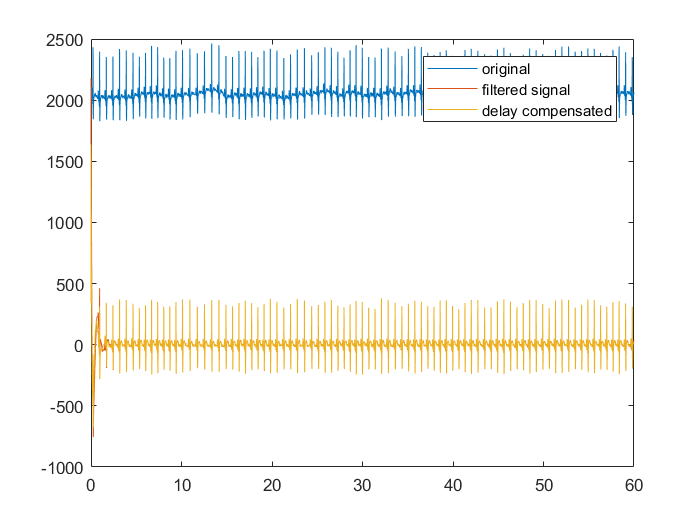

ecg_lastMin_blRemoved_delayCompensated=filtfilt(b,a,ecg_lastMin_blRemoved);
plot([0:length(ecg_lastMin_normalised)-1]./Fs,ecg_lastMin);
hold on
plot([0:length(ecg_lastMin_normalised)-1]./Fs,ecg_lastMin_blRemoved);
plot([0:length(ecg_lastMin_normalised)-1]./Fs,ecg_lastMin_blRemoved_delayCompensated);
hold off
legend('original','filtered signal','delay compensated');

mean_offset_signal=ecg_lastMin-mean(ecg_lastMin);
y=fft(mean_offset_signal);
p2=abs(y/length(y));
signalp1=p2(1:length(y)/2+1);
signalp1(2 : end-1) = 2 * signalp1(2 : end-1);
f=256*(0:length(y)/2)/length(y);
plot(f,signalp1)


% Remove trend from data
detrendedData = detrend(ecg_lastMin,3);

% Display results
clf
plot(ecg_lastMin,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(detrendedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(ecg_lastMin-detrendedData,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

% Smooth input data
smoothedData = smoothdata(ecg_lastMin,"movmean","SmoothingFactor",0.25);

% Display results
clf
plot(ecg_lastMin,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(smoothedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend
% trend=sgolayfilt(ecg_lastMin,3,9999);
% detrended_signal=ecg_lastMin-trend;
% plot(ecg_lastMin),hold on
% plot(detrended_signal),hold off
% legend('wt','dt')

[heartbeat_bpm,locs]=find_heartbeat(ecg_lastMin,Fs);
rr=diff(locs/ECG_SamplingRate);
pkMean = mean(rr);
pk2STD = std(rr) * 1.92;
rejectMax = pkMean + pk2STD;
rejectMin = pkMean - pk2STD;
ArrReject = find((rr > rejectMax) | (rr < rejectMin));
rrA=rr;
pkTimesA=locs(1:end-1)/ECG_SamplingRate;
rr(ArrReject) = [];
pkTimes(ArrReject) = [];

Heart Rate=84


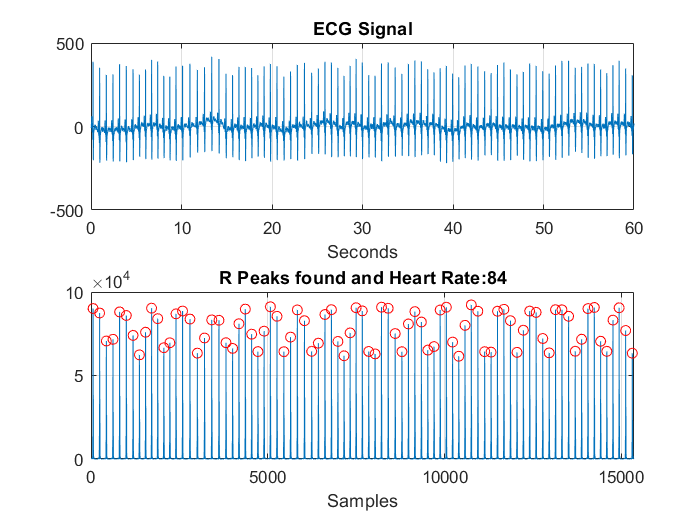

% Importing the signal
if ~exist('Data','var')
    load("/home/dsplab/Prosthetic arm/Emotion detection/ECG/resources/datasets/DREAMER/ECG_sample_dataset.mat");
end

% RAW signal
Fs=ECG_SamplingRate;
samples_per_min=Fs*60;
ecg_lastMin=Data.ECG.stimuli{1,1}(end-samples_per_min+1:end,1);

%Eliminate the offset
ecg_lastMin=ecg_lastMin-mean(ecg_lastMin);

% Finding peaks
[heartbeat_bpm,locs]=find_heartbeat(ecg_lastMin,Fs);


if(0)
% Rejects all noise from RR-Interval data
rr_interval=diff(locs/ECG_SamplingRate);
pkMean = mean(rr_interval);
pk2STD = std(rr_interval) * 1.92;
rejectMax = pkMean + pk2STD;
rejectMin = pkMean - pk2STD;
ArrReject = find((rr_interval > rejectMax) | (rr_interval < rejectMin));


% plotting Rejectes points
pkTimes=locs(1:end-1)/ECG_SamplingRate;
reject = zeros(length(ArrReject),2);                    
for i = 1:length(ArrReject)
reject(i,1) = rr_interval(ArrReject(i));
reject(i,2) = pkTimes(ArrReject(i));
end
plot(pkTimes,rr_interval,'b'), hold on
scatter(reject(:,2),reject(:,1),'ro')
yline(rejectMax,'--r')
yline(rejectMin,'--r')
ylabel('RR Intervals(s)')
xlabel('Time (s)')
title('RR Interval Series Showing Rejected Points')
hold off

% Rejects all noise from RR-Interval data (cond)
rrA=rr_interval;
pkTimes=locs(1:end-1)/ECG_SamplingRate;
pkTimesA=pkTimes;
rr_interval(ArrReject) = [];
pkTimes(ArrReject) = [];

end

% Statistical features
rr_interval=diff(locs/ECG_SamplingRate)*1000; %in ms
AVG_RR=mean(rr_interval);
RR_Range=[max(rr_interval) min(rr_interval)];

SD_RR=std(rr_interval);
RMS_RR=sqrt(mean(rr_interval.^2));

RR50=sum(abs(diff(rr_interval))>(50/1000));

pRR50=(RR50/length(rr_interval))*100;

%poincare map
pmX = rr_interval;
pmX(end)=[];         
pmY = rr_interval;
pmY(1)=[];
SD1 = std(pmX - pmY);
SD2 = std(pmX + pmY);

% Resample HRV
FsHRV=4;
THRV = 1/FsHRV;
pkTimes=locs(1:end-1)/ECG_SamplingRate;
HRV_R = resample(rr_interval,pkTimes,FsHRV);
LHRV = length(HRV_R);
tHRV = (0:LHRV-1)'*THRV;

% Spectral features
yF = fft(HRV_R);
p2 = abs(yF/LHRV);
p1 = p2(1 : LHRV/2 + 1);
p1(2 : end-1) = 2 * p1(2 : end-1);          
fftHRV = FsHRV * (0 : (LHRV/2)) / LHRV;
    % LF           
NOTlf = find(fftHRV < 0.04 | fftHRV > 0.15);
lf = fftHRV;
lf(NOTlf) = [];
p1LF = p1;
p1LF(NOTlf) = [];
lfPower = sum(p1LF);
    % HF
NOThf = find((fftHRV > 0.4) | fftHRV < max(lf)); %| fftHRV < 0.15);
hf = fftHRV;
hf(NOThf) = [];           
p1HF = p1;
p1HF(NOThf) = [];
hfPower = sum(p1HF);
    %Total Power
lowFreqHighFreqRatio = lfPower/hfPower;
TotPower = lfPower + hfPower;
LFperc = lfPower*100/(lfPower + hfPower);
HFperc = 100-LFperc;


% plot FFT
y = fft(ecg_lastMin);
len=length(ecg_lastMin)

len = 15360

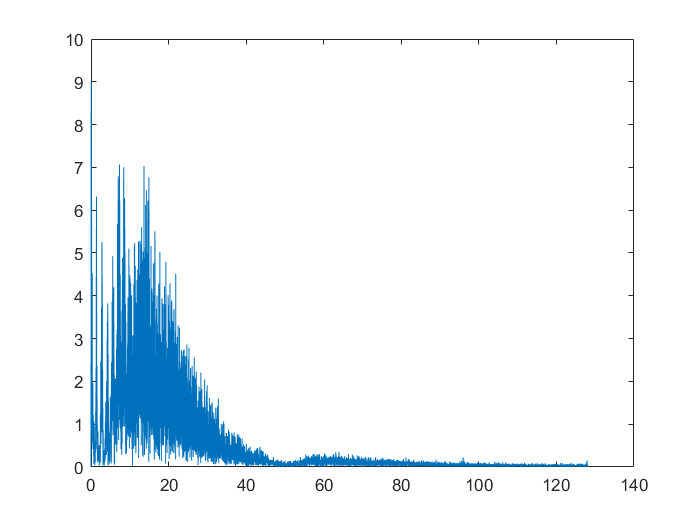

p2 = abs(y/len);
signalp1 = p2(1 : len/2 + 1);
signalp1(2 : end-1) = 2 * signalp1(2 : end-1);
f = Fs * (0 : (len/2)) / len;
figure;
plot(f,signalp1)

ao.plotRRinterval

Undefined variable "ao" or class "ao.plotRRinterval".

hold on
plot(rr_interval/1000)
hold off
legend('1','2')